clear all
close all
clc

## Loading In Audio

handel = load("handel.mat");
laughter = load("laughter.mat");
handel.y = handel.y(linspace(1,handel.Fs*5,handel.Fs*5));
laughter.y = laughter.y(linspace(1,laughter.Fs*5,laughter.Fs*5));

## Creating our 2kHz lowpass filter and applying it

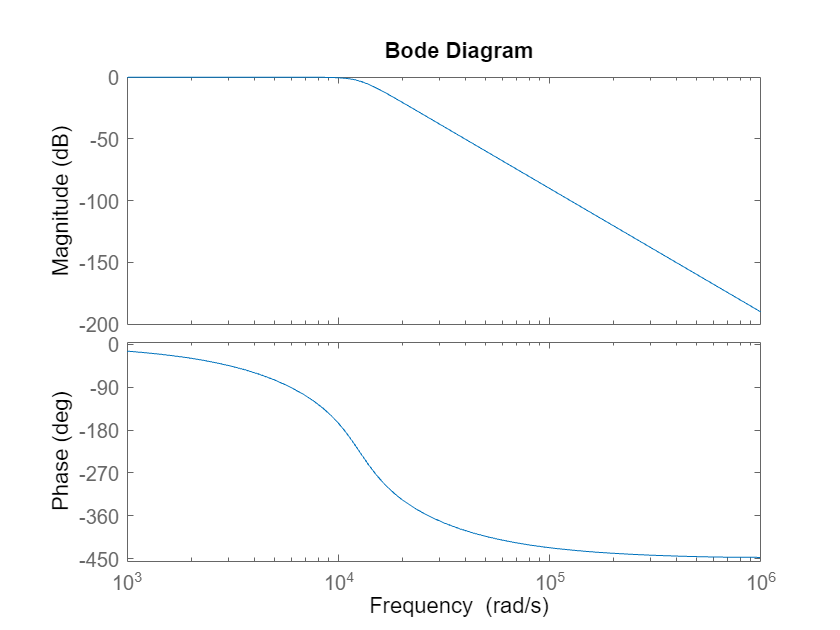

fc = 2000; % Hz Cutoff Frequency
[num, den] = butter(5,2*pi*fc,"low",'s');
H_butter = tf(num,den);
timevec = linspace(0,5,40960);
handel.y = lsim(H_butter,transpose(handel.y),timevec);
laughter.y = lsim(H_butter,transpose(laughter.y),timevec);
clear num den
bodeplot(H_butter)

## Normalizing the signals to [0,2] and upsampling to 120 kHz

target_samples = 120000;
samp_rate = target_samples/5;
handel.y = resample((1.+(handel.y./(max(abs(handel.y))))),target_samples,length(handel.y));
laughter.y = resample((1.+(laughter.y./(max(abs(laughter.y))))),target_samples,length(laughter.y));
handel.Fs = samp_rate;
laughter.Fs = samp_rate;

## Carrier Signals

tlength = linspace(0,5,target_samples);
ThirtyKHz= transpose(cos(30000*2*pi*tlength));% 30 KHz
TwentyKHz = transpose(cos(20000*2*pi*tlength));% 20 KHz

## Multiplying The Signals

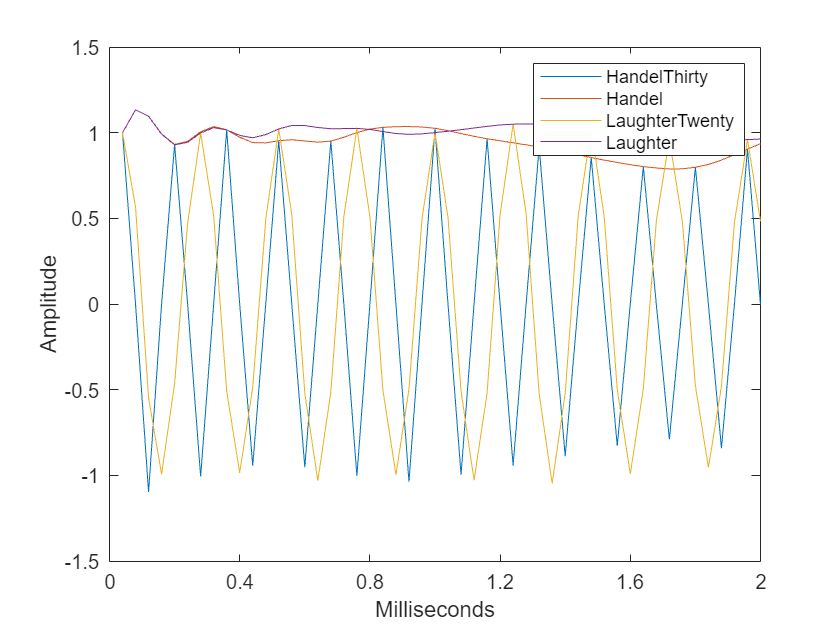

% Modulating the handel sample with the thirtykhz
handelthirty = handel.y.*ThirtyKHz;
% Modulating the laughter sample with the twenty khz
laughtertwenty = laughter.y.*TwentyKHz;
% Adding these two together
SignalSum = handelthirty+laughtertwenty;
plot(handelthirty)
hold on
plot(handel.y)
hold on
plot(laughtertwenty)
hold on
plot(laughter.y)
hold on
xlim([0,50]);
legend('HandelThirty','Handel','LaughterTwenty','Laughter');
xticklabels({0,.4,.8,1.2,1.6,2})
xlabel('Milliseconds')
ylabel('Amplitude')
hold off

## Examining With MyFFT

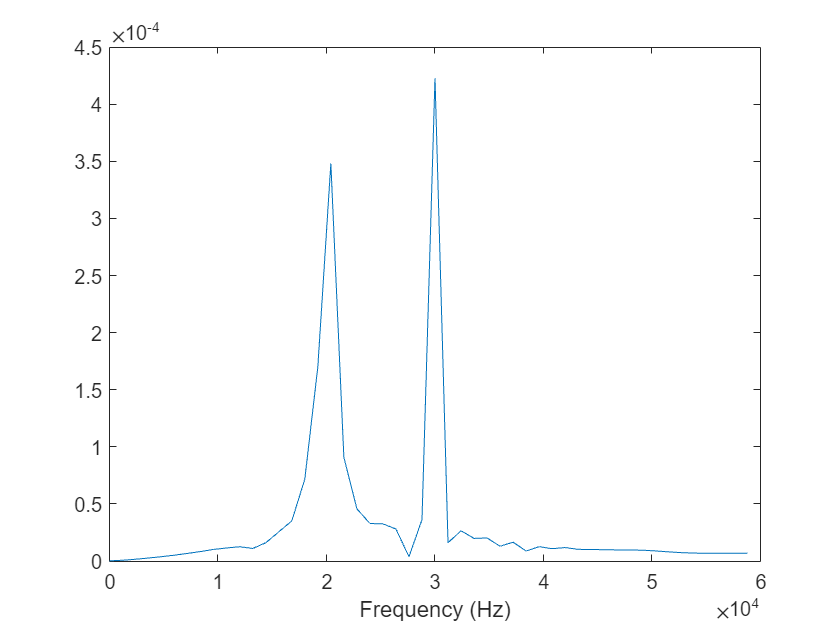

myFFT(SignalSum,120000,100)

## Band Pass For 20KHz and 30KHz

filteredhandel =          0
    0.0000
    0.0000
   -0.0000
   -0.0001
    0.0000
    0.0006
    0.0002
   -0.0016
   -0.0016


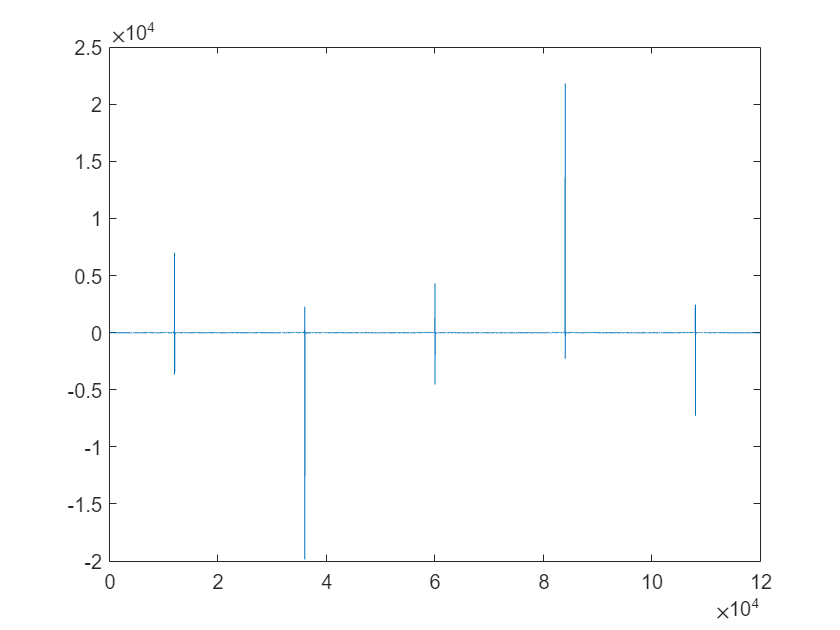

[num, den] = butter(5,[10000 26000],"bandpass","s");
TwentyKHzBand = tf(num,den);
[num, den] = butter(5,[28000 32000],"bandpass","s");
ThirtyKHzBand = tf(num,den);
timevec = linspace(0,5,120000);

filteredlaughter = lsim(TwentyKHzBand,transpose(SignalSum),timevec);
filteredhandel = lsim(ThirtyKHzBand,transpose(SignalSum),timevec);

## Demodulation

[hupper,hlower] = envelope(filteredhandel);
[lupper,llower] = envelope(filteredlaughter);